# Scan Detector Plotter

## Directory and Internal Libraries/Functions

Sets paths easily to run, calling functions that import different data types

clear
clf
cd 'C:\Users\johns\Documents\Github\QEM-MATLAB\Plotters\201029 xDBL Scan Plotting'
addpath( 'C:\Users\johns\Documents\Github\QEM-MATLAB', ...  % LT Spice output response
    'G:\My Drive\Projects');

% Recursive addpath
addpath(genpath('G:\My Drive\Projects\xDBL DoublePass'));

load('ImpVariables.mat')


## Return Home

cd 'C:\Users\johns\Documents\Github\QEM-MATLAB\Plotters\201029 xDBL Scan Plotting'

## Jump to Data Folder

%cd 'G:\My Drive\Projects\xDBL DoublePass\PN Junction Exp\201029 xDBL CleavedScanTest\RawScanData'

## Load Data

clear
clf
load data.mat
% plot(data.a1(:,1),data.a1(:,2))
% plot(data.a2(:,1),data.a2(:,2))
% plot(data.a3(:,1),data.a3(:,2))

scan5kV = data.a2

scan5kV = 	1.0e+04 *

         0    0.0000
    0.0264    0.0000
    0.0528    0.0000
    0.0792    0.0000
    0.1056    0.0000
    0.1320    0.0000
    0.1584    0.0000
    0.1848    0.0000
    0.2112    0.0000
    0.2376    0.0000


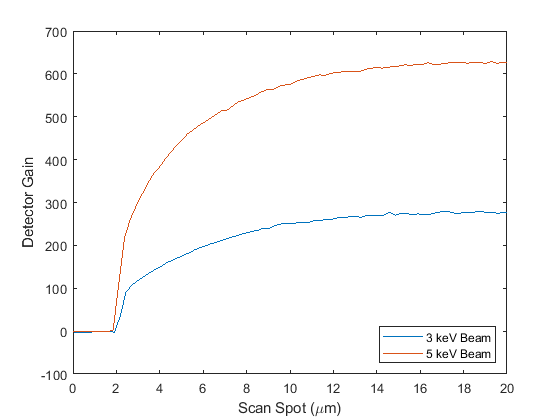

scan5kV_odd = data.a3;
scan3kV = data.a1;

readScan = scan3kV;
readScan(:,2) = - readScan(:,2) + readScan(1,2); %Normalizes and flips sign
readStart = 1;
readEnd = 78;
readScan = readScan(readStart:readEnd,:);
deriv = (readScan(1:end-1, 2) - readScan(2:end,2));
readScan1 = readScan; deriv1 = deriv;
plotShift = 0.2;

readScan = scan5kV;
readScan(:,2) = - readScan(:,2) + readScan(1,2); %Normalizes and flips sign
readStart = 1;
readEnd = 78;
readScan = readScan(readStart:readEnd,:);
deriv = (readScan(1:end-1, 2) - readScan(2:end,2));
readScan2 = readScan; deriv2 = deriv;

figure(1)
plot(readScan1(:,1)/1e3-plotShift,readScan1(:,2)/(10e-12),...
     readScan2(:,1)/1e3,readScan2(:,2)/(10e-12))
xlabel('Scan Spot (\mum)')
ylabel('Detector Gain')
xlim([0 20])
legend(['3 keV Beam'; '5 keV Beam'], 'location', 'southeast')

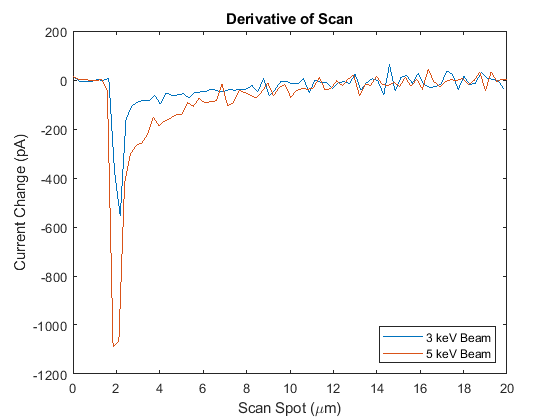



figure(2)
plot(readScan1(1:end-1,1)/1e3-plotShift,deriv1*1e12, ...
     readScan2(1:end-1,1)/1e3,deriv2*1e12)
title('Derivative of Scan')
xlim([0 20])
title('Derivative of Scan')
xlabel('Scan Spot (\mum)')
ylabel('Current Change (pA)')
legend(['3 keV Beam'; '5 keV Beam'], 'location', 'southeast')

## Plot Full    

% figure(1)
% hold on
% plot(readScan(:,1)/1e3,readScan(:,2)/(10e-12))
% xlabel('Scan Spot (\mum)')
% ylabel('Detector Gain')
% hold off
% 

## Plot Derivative

% hold on
% figure(2)
% plot(readScan(1:end-1,1),deriv*1e9)
% title('Derivative of Scan')
% xlabel('Scan Spot (\mum)')
% ylabel('Current Change (nA)')
% hold off